# Alpha Dataset

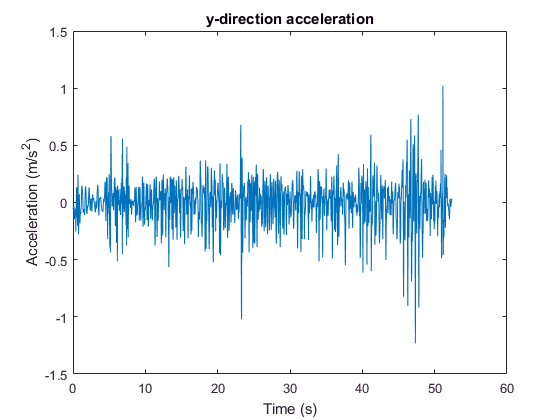

load cheerleadertrunk.mat
Fs = 100;
t_omi = linspace(0,length(cheerleaderomi(:,1))/Fs,length(cheerleaderomi(:,1)));
plot(t_omi,cheerleaderomi(:,5))
title('y-direction acceleration')
xlabel('Time (s)')
ylabel('Acceleration (m/s^2)')

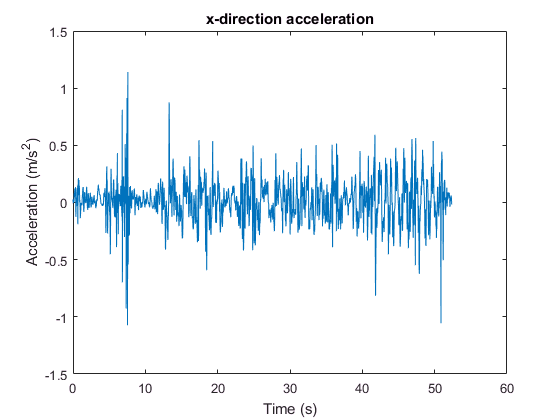

plot(t_omi,cheerleaderomi(:,6))
title('x-direction acceleration')
xlabel('Time (s)')
ylabel('Acceleration (m/s^2)')

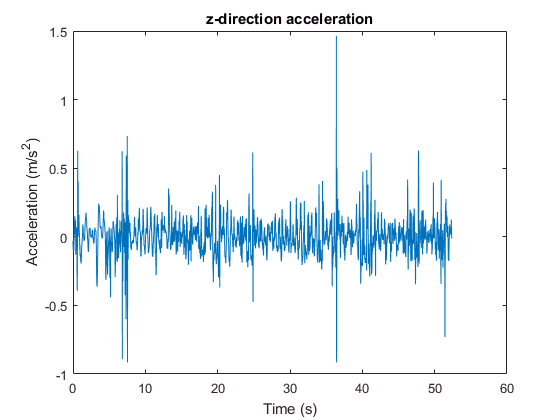

plot(t_omi,cheerleaderomi(:,7))
title('z-direction acceleration')
xlabel('Time (s)')
ylabel('Acceleration (m/s^2)')

mean(abs(cheerleaderomi(:,5)))

ans = 0.1261

mean(abs(cheerleaderomi(:,6)))

ans = 0.1239

mean(abs(cheerleaderomi(:,7)))

ans = 0.0869

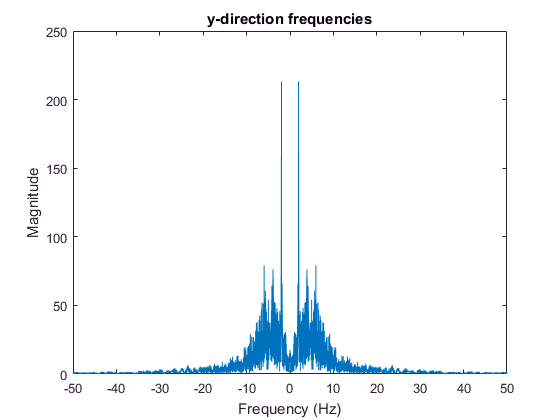

N_omi = length(cheerleaderomi(:,1));
f_omi = linspace(-Fs/2, Fs/2 - Fs/N_omi, N_omi) + Fs/(2*N_omi)*mod(N_omi,2);
plot(f_omi,fftshift(abs(fft(cheerleaderomi(:,5)))));
title('y-direction frequencies')
xlabel('Frequency (Hz)')
ylabel('Magnitude')

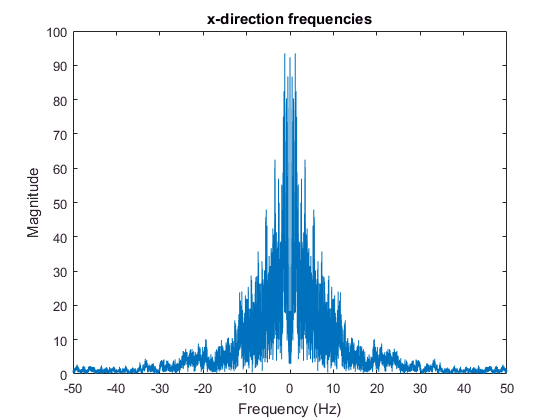

plot(f_omi,fftshift(abs(fft(cheerleaderomi(:,6)))));
title('x-direction frequencies')
xlabel('Frequency (Hz)')
ylabel('Magnitude')

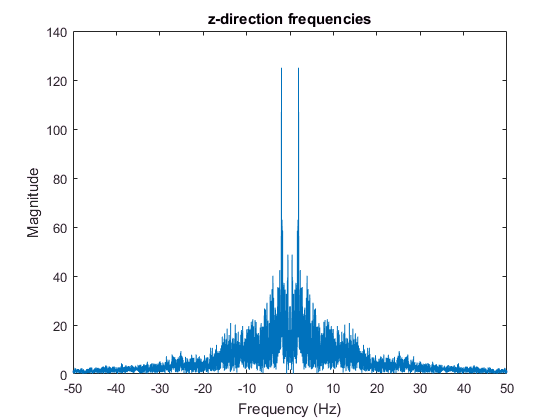

plot(f_omi,fftshift(abs(fft(cheerleaderomi(:,7)))));
title('z-direction frequencies')
xlabel('Frequency (Hz)')
ylabel('Magnitude')

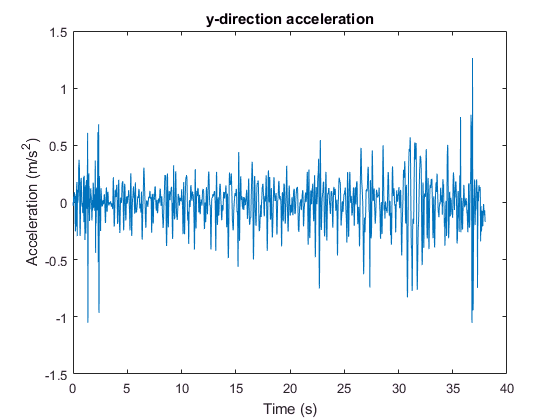

load ushertrunk.mat
Fs = 100;
t_usher = linspace(0,length(usher(:,1))/Fs,length(usher(:,1)));
plot(t_usher,usher(:,5))
title('y-direction acceleration')
xlabel('Time (s)')
ylabel('Acceleration (m/s^2)')

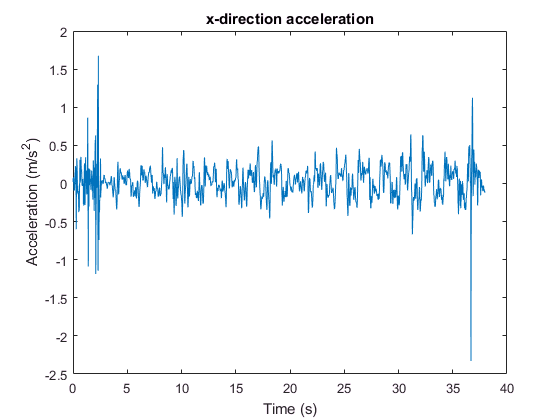

plot(t_usher,usher(:,6))
title('x-direction acceleration')
xlabel('Time (s)')
ylabel('Acceleration (m/s^2)')

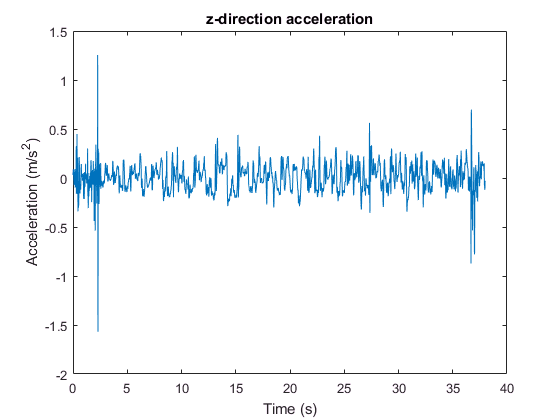

plot(t_usher,usher(:,7))
title('z-direction acceleration')
xlabel('Time (s)')
ylabel('Acceleration (m/s^2)');

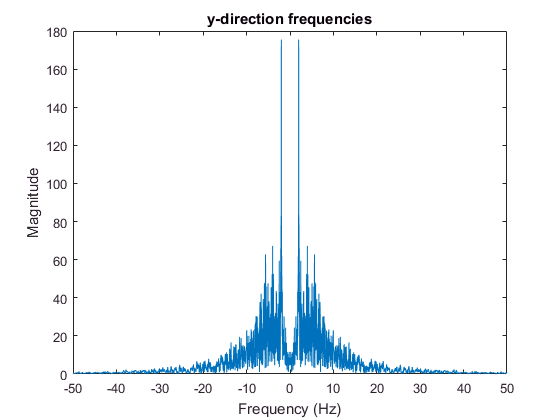

N_usher = length(usher(:,1));
f_usher = linspace(-Fs/2, Fs/2 - Fs/N_usher, N_usher) + Fs/(2*N_usher)*mod(N_usher,2);
plot(f_usher,fftshift(abs(fft(usher(:,5)))));
title('y-direction frequencies')
xlabel('Frequency (Hz)')
ylabel('Magnitude')

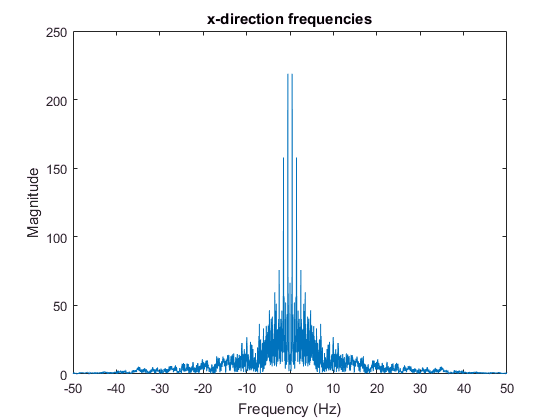

plot(f_usher,fftshift(abs(fft(usher(:,6)))));
title('x-direction frequencies')
xlabel('Frequency (Hz)')
ylabel('Magnitude')

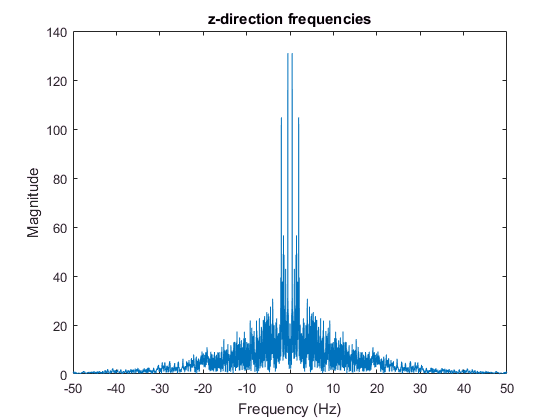

plot(f_usher,fftshift(abs(fft(usher(:,7)))));
title('z-direction frequencies')
xlabel('Frequency (Hz)')
ylabel('Magnitude')

load bonfiretrunk.mat
N_bonfire = length(bonfire(:,1));
t_bonfire = linspace(0,N_bonfire/Fs,N_bonfire);
f_bonfire = linspace(-Fs/2, Fs/2 - Fs/N_bonfire, N_bonfire) + Fs/(2*N_bonfire)*mod(N_bonfire,2);

load bonfirearm.mat
N_bonfirehand = length(bonfirehand(:,1));
t_bonfirehand = linspace(0,N_bonfirehand/Fs,N_bonfirehand);
f_bonfirehand = linspace(-Fs/2, Fs/2 - Fs/N_bonfirehand, N_bonfirehand) + Fs/(2*N_bonfirehand)*mod(N_bonfirehand,2);

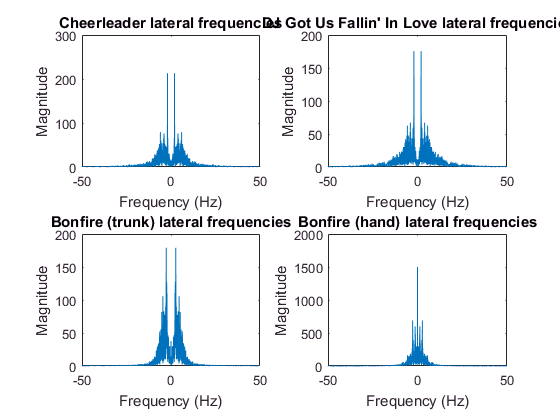

figure
subplot(2,2,1)
plot(f_omi,fftshift(abs(fft(cheerleaderomi(:,5)))));
title('Cheerleader lateral frequencies')
xlabel('Frequency (Hz)')
ylabel('Magnitude')
subplot(2,2,2)
plot(f_usher,fftshift(abs(fft(usher(:,5)))));
title("DJ Got Us Fallin' In Love lateral frequencies")
xlabel('Frequency (Hz)')
ylabel('Magnitude')
subplot(2,2,3)
plot(f_bonfire, fftshift(abs(fft(bonfire(:,5)))));
title("Bonfire (trunk) lateral frequencies")
xlabel('Frequency (Hz)')
ylabel('Magnitude')
subplot(2,2,4)
plot(f_bonfirehand, fftshift(abs(fft(bonfirehand(:,5)))));
title('Bonfire (hand) lateral frequencies')
xlabel('Frequency (Hz)')
ylabel('Magnitude')

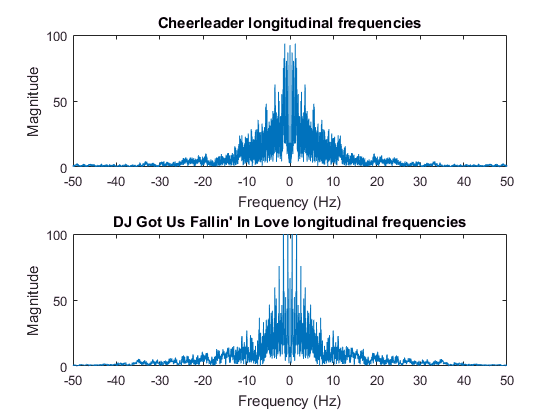

figure
subplot(2,1,1)
plot(f_omi,fftshift(abs(fft(cheerleaderomi(:,6)))));
title('Cheerleader longitudinal frequencies')
xlabel('Frequency (Hz)')
ylabel('Magnitude')
subplot(2,1,2)
plot(f_usher,fftshift(abs(fft(usher(:,6)))));
ylim([0, 100])
title("DJ Got Us Fallin' In Love longitudinal frequencies")
xlabel('Frequency (Hz)')
ylabel('Magnitude')

We went backwards to validate our data. We found two songs that have very similar BPM and then attached the accelerometer to a dancer's hip and collected data. We took the FFT of this data and compared it to each other, and found that the data looked very similar, especially in the side-to-side direction. This validated the concept that people dancing to songs with similar bpms will show similar accelerations/frequencies. The goal would now be to figure out ways to relate acceleration to bpm.

[N_omi, t_omi, f_omi, mag_omi, bpm_omi] = findbpm('cheerleadertrunk.mat', 100)

N_omi = 5236

t_omi =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2701    0.2801    0.2901    0.3001    0.3101    0.3201    0.3301    0.3401    0.3501    0.3601    0.3701    0.3801    0.3901    0.4001    0.4101    0.4201    0.4301    0.4401    0.4501    0.4601    0.4701    0.4801    0.4901


f_omi =   -50.0000  -49.9809  -49.9618  -49.9427  -49.9236  -49.9045  -49.8854  -49.8663  -49.8472  -49.8281  -49.8090  -49.7899  -49.7708  -49.7517  -49.7326  -49.7135  -49.6944  -49.6753  -49.6562  -49.6371  -49.6180  -49.5989  -49.5798  -49.5607  -49.5416  -49.5225  -49.5034  -49.4843  -49.4652  -49.4461  -49.4270  -49.4079  -49.3888  -49.3697  -49.3506  -49.3316  -49.3125  -49.2934  -49.2743  -49.2552  -49.2361  -49.2170  -49.1979  -49.1788  -49.1597  -49.1406  -49.1215  -49.1024  -49.0833  -49.0642


mag_omi =     2.0717
    2.8398
    1.9924
    3.4068
    3.0235
    2.4404
    3.5508
    1.1963
    3.2826
    1.4800


bpm_omi = 66.4629

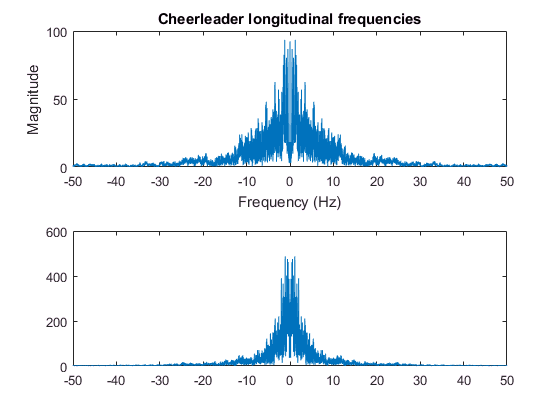

plot(f_omi,mag_omi)

function [N, t, f, mag, bpm] = findbpm(filename, Fs)
    file = cell2mat(struct2cell(load(filename)));
    N = length(file(:,1));
    t = linspace(0,N/Fs,N);
    f = linspace(-Fs/2, Fs/2 - Fs/N, N) + Fs/(2*N)*mod(N,2);
    mag = fftshift(abs(fft(file(:,2))));
    
    positive = mag(f > 0);
    H = max(positive);
    bps = find(mag == H);
    bpm = abs(f(bps(1)))*60;
end
